# Chapter 6, Section 2 (Part 1)

The goal of this activity is to introduce what are known as orthogonal and orthonormal sets. Before we make the definitions, recall that two vectors $\textbf u$ and $\textbf v$ are orthogonal if and only if $\textbf u\cdot\textbf v=0$.

**Definition: **Let $V$ be a vector space. A set of vectors $\left\{\textbf v_1,\ \textbf v_2,\ \ldots,\ \textbf v_n\right\}$ is called an **orthogonal set** if the vectors $\textbf v_1,\ \textbf v_2,\ \ldots,\ \textbf v_n$ are mutually orthogonal. The phrase "mutually orthogonal" means each pair of vectors $\textbf v_i$ and $\textbf v_j$, where $i\ne j$, are orthogonal. 

# Example #1

Is the set


$$S=\left\{\pmatrix{1\cr -1\cr 1},\ \pmatrix{0\cr 1\cr 1},\ \pmatrix{-2\cr -1\cr 1}\right\}$$


an orthogonal set?

**Solution:** The set $S$ is an orthogonal set if and only if the vectors are mutually orthogonal; that is, each pair of vectors are orthogonal. Let's check the first two.


$$\begin{array}{rcl}
\textbf u_1\cdot\textbf u_2
&=&\pmatrix{1\cr -1\cr 1}\cdot\pmatrix{0\cr 1\cr 1}\\
&=&(1)(0)+(-1)(1)+(1)(1)\\
&=&0-1+1\\
&=&0
\end{array}$$


Yes, $\textbf u_1$ and $\textbf u_2$ are orthogonal, because their dot product equals zero. Now, what about the first and third vectors?


$$\begin{array}{rcl}
\textbf u_1\cdot\textbf u_3
&=&\pmatrix{1\cr -1\cr 1}\cdot\pmatrix{-2\cr -1\cr 1}\\
&=&(1)(-2)+(-1)(-1)+(1)(1)\\
&=&-2+1+1\\
&=&0
\end{array}$$


Yes, $\textbf u_1$ and $\textbf u_3$ are orthogonal, because their dot product equals zero. Now, what about the second and third vectors?


$$\begin{array}{rcl}
\textbf u_2\cdot\textbf u_3
&=&\pmatrix{0\cr 1\cr 1}\cdot\pmatrix{-2\cr -1\cr 1}\\
&=&(0)(-2)+(1)(-1)+(1)(1)\\
&=&0-1+1\\
&=&0
\end{array}$$


Yes, $\textbf u_2$ and $\textbf u_3$ are orthogonal, because their dot product equals zero. Of course, we can check this with Matlab.

u1=[1;-1;1];
u2=[0;1;1];
u3=[-2;-1;1];
dot(u1,u2)

ans = 0

dot(u1,u3)

ans = 0

dot(u2,u3)

ans = 0

Yes, the dot product of all three pairs is zero, so they are mutually orthogonal and we've shown that the set $S$ is an orthogonal set of vectors. Now, what do they look like?

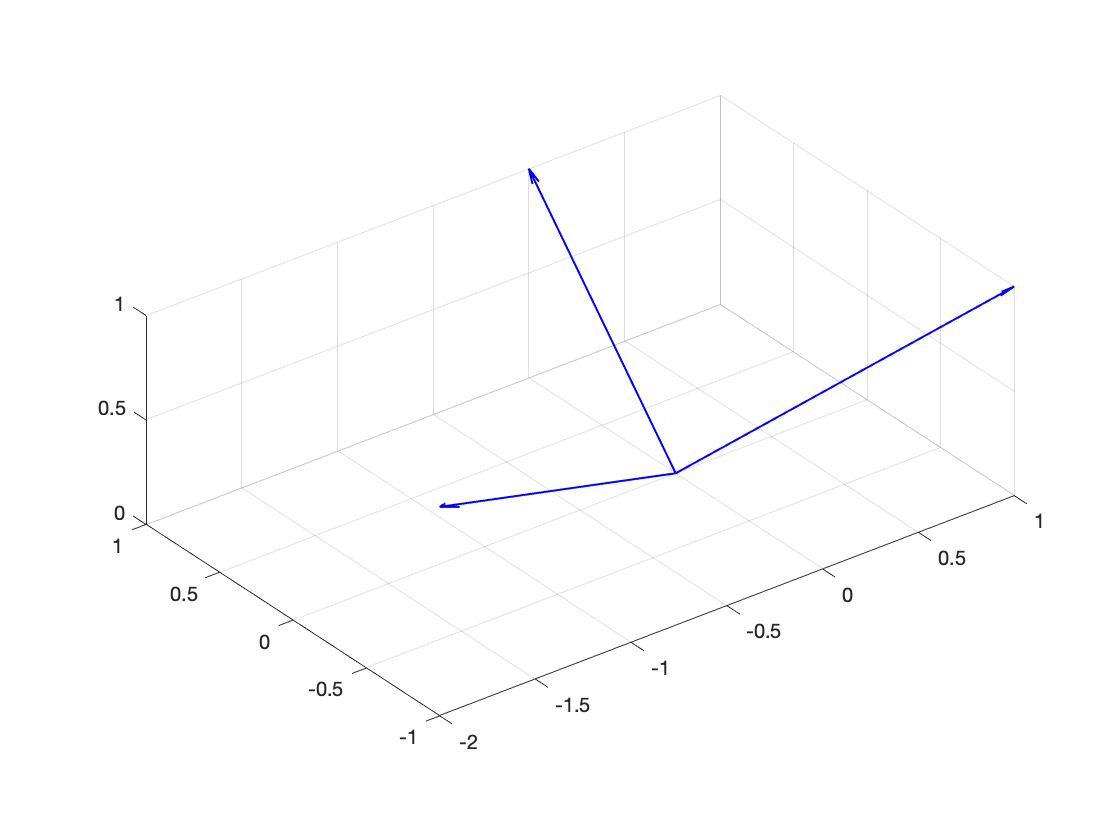

figure
quiver3(0,0,0,u1(1),u1(2),u1(3),0,'LineWidth',1,'Color','b')
hold on
quiver3(0,0,0,u2(1),u2(2),u2(3),0,'LineWidth',1,'Color','b')
quiver3(0,0,0,u3(1),u3(2),u3(3),0,'LineWidth',1,'Color','b')
axis equal

Now, have some fun rotating the image to different views that show clear evidence that each vector is orthogonal to each vector. 

# Example #2

Describe the set of all vectors that are orthogonal to the vector $\textbf u=(2,1)^T$.

**Solution:** Let $\textbf v=(x,y)^T$ be any vector that is orthogonal to the vector $\textbf u=(2,1)^T$.  This means that the dot product of $\textbf u$ and $\textbf v$ is zero, regardless of $x$ and $y$, so we can write:


$$\begin{array}{rcl}
\textbf u\cdot\textbf v&=&0\\
\pmatrix{2\cr 1}\cdot\pmatrix{x\cr y}&=&0\\
2x+y&=&0\\
y&=&-2x
\end{array}$$


So, the set of all vectors $\textbf v=(x,y)^T$ that are orthogonal to $\textbf u=(2,1)^T$ lie on the line $y=-2x$. Let's draw an image. The axis equal command provides the same scale on each axis so that the vector and line appear to be perpendicular.

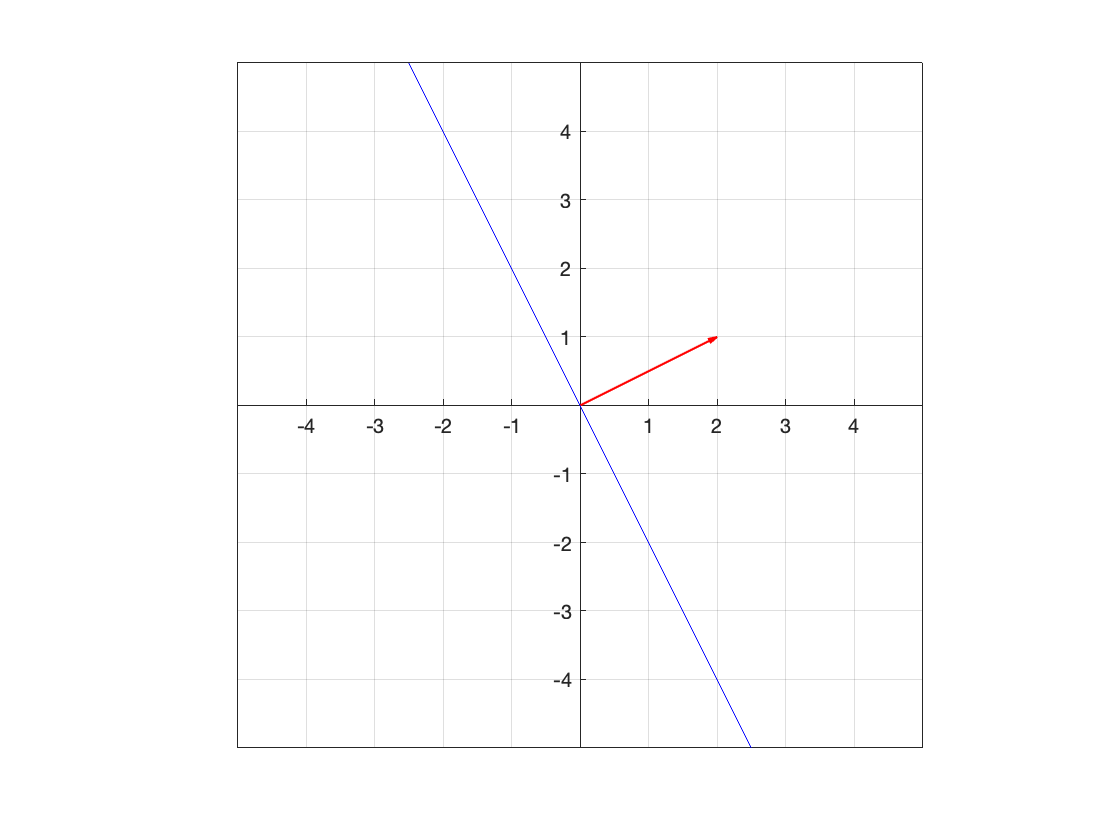

figure
u=[2;1];
quiver(0,0,u(1),u(2),0,'LineWidth',1,'Color','r')
hold on
x=linspace(-5,5);
y=-2*x;
plot(x,y,'Color','b')
grid on
axis equal
axis([-5,5,-5,5])
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
hold off

Another way to find the set of all vectors that are orthogonal to the vector $\textbf u=(2,1)^T$ is to make a guess for a vector that is orthogonal to the vector $\textbf u=(2,1)^T$, such as $\vec v=(-1,2)^T$. We can verify that these two vectors are orthogonal by taking their dot product.


$$\begin{array}{rcl}
\textbf u\cdot\textbf v&=&\pmatrix{2\cr 1}\cdot\pmatrix{-1\cr 2}\\
&=&(2)(-1)+(1)(2)\\
&=&0
\end{array}$$


Because the dot product is zero, these two vectors are orthogonal. Now, any scalar multiple of $\textbf v=(-1,2)^T$ will be parallel to $\textbf v=(-1,2)^T$, and thus orthogonal to $\textbf u=(2,1)^T$.  Therefore, any vector $\textbf w=(x,y)^T$ that is orthogonal to $\textbf u=(2,1)^T$ will be a scalar multiple of $\textbf v=(-1,2)^T$. That is,


$$\begin{array}{rcl}
\textbf w&=&t\textbf v\\
\pmatrix{x\cr y}&=&t\pmatrix{-1\cr 2}\\
\pmatrix{x\cr y}&=&\pmatrix{-t\cr 2t}
\end{array}$$


Therefore, $x=-t$ and $y=2t$ should be the equation of the same line. Let's see if this is true.

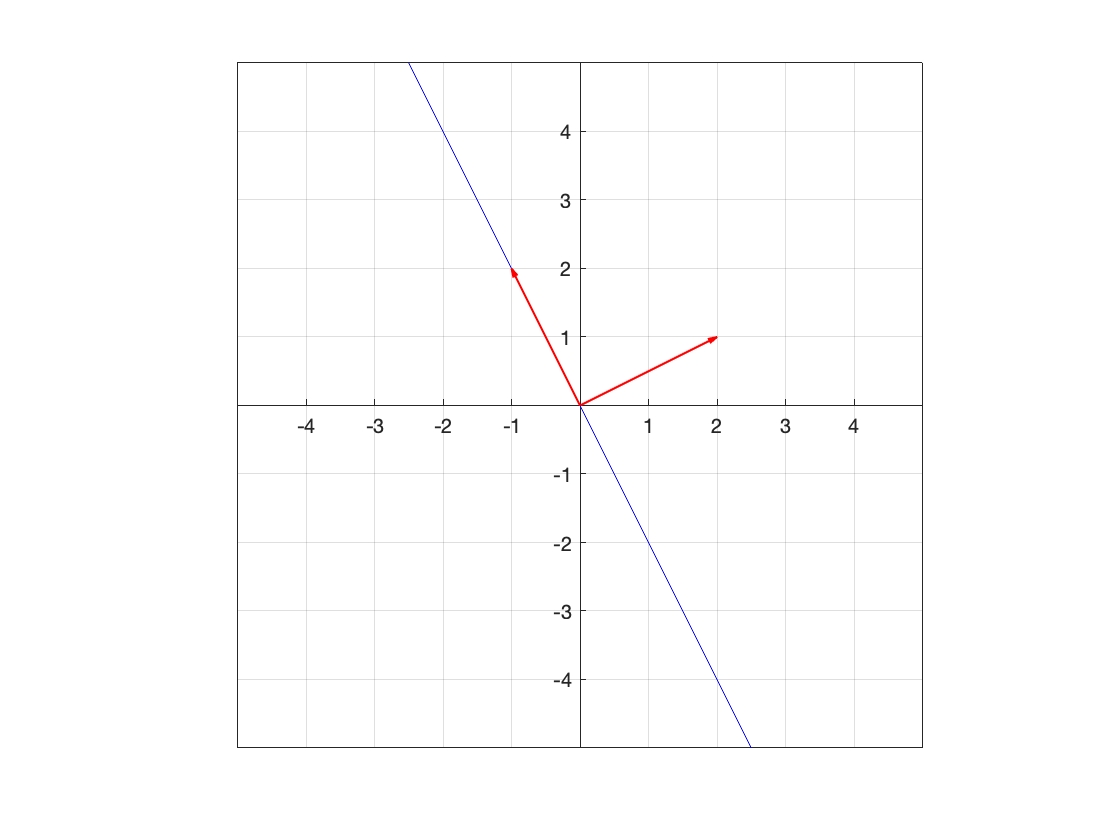

figure
u=[2;1];
quiver(0,0,u(1),u(2),0,'LineWidth',1,'Color','r')
hold on
t=linspace(-5,5);
x=-t;
y=2*t;
plot(x,y,'Color','b')
quiver(0,0,-1,2,0,'LineWidth',1,'Color','r')
grid on
axis equal
axis([-5,5,-5,5])
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
hold off

Same image. Note that we added the vector $\textbf v=(-1,2)^T$ to this second image to show that all vectors lying on our blue line are scalar multiples of $\textbf v=(-1,2)^T$ and orthogonal to $\textbf u=(2,1)^T$.

# Example #3

Describe the set of vectors that are orthogonal to the vector $u=(1,-1,1)^T$.

**Solution:** Let $\textbf v=(x,y,z)^T$ be any vector that is orthogonal to $\textbf u=(1,-1,1)^T$. Then we can write:


$$\begin{array}{rcl}
\textbf u\cdot\textbf v&=&0\\
\pmatrix{1\cr -1\cr 1}\cdot\pmatrix{x\cr y\cr z}&=&0\\
(1)(x)+(-1)(y)+(1)(z)&=&0\\
x-y+z&=&0
\end{array}$$


This is an equation of a plane that passes through the origin.  Let's draw an image. First, solve for $z$.


$$z=-x+y$$


Now we'll sketch this plane and add the vector $u=(1,-1,1)^T$. Again, the axis equal command scales the axes so that each has the same scale (important when you want to view orthogonality).

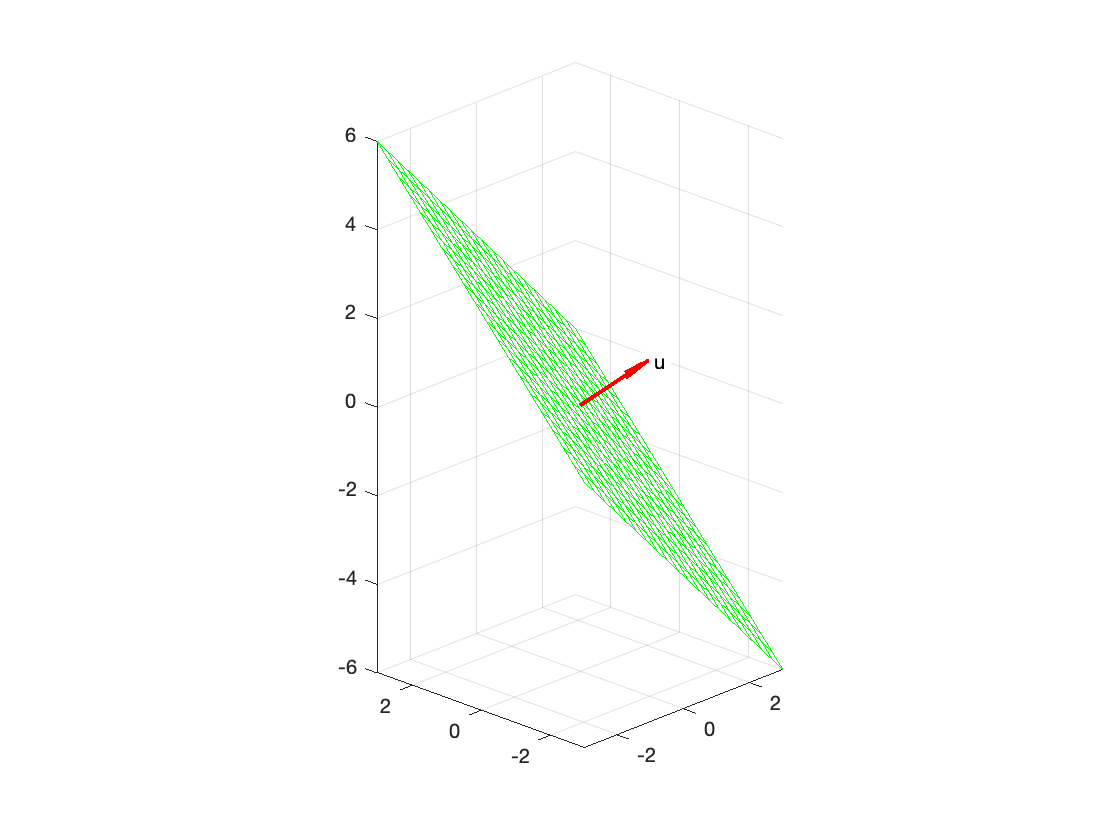

figure
u=[1;-1;1];
x=linspace(-3,3,20);
y=linspace(-3,3,20);
[X,Y]=meshgrid(x,y);
Z=-X+Y;
mesh(X,Y,Z,'EdgeColor','g','FaceAlpha',0.2)
hold on
quiver3(0,0,0,u(1),u(2),u(3),0,'LineWidth',2,'Color','r','MaxHeadSize',2)
text(1,-1,1,' u','BackgroundColor','w')
hold off
axis equal
view([-46.2 22.2])
hold off

Readers might want to rotate this image to convince themselves that $\textbf v$ is orthogonal to the plane. Another way to perform this task is to guess two vectors that are orthogonal to the vector $\textbf u=(1,-1,1)^T$. Note that:


$$\pmatrix{1\cr -1\cr 1}\cdot\pmatrix{0\cr 1\cr 1}=0\qquad\text{and}\qquad\pmatrix{1\cr -1\cr 1}\cdot\pmatrix{-2\cr -1\cr 1}=0$$


Thus, $\textbf u=(1,-1,1)^T$ is orthogonal to each of the vectors $\textbf v=(0,1,1)^T$ and $\textbf w=(-2,-1,1)^T#$.  Now, we can show that $\textbf u$ is orthogonal to any linear combination of the vectors $\textbf v$ and $\textbf w$.


$$\begin{array}{rcl}
\textbf u\cdot(c_1\textbf v+c_2\textbf w)&=&\textbf u\cdot (c_1\textbf v)+\textbf u\cdot(c_2\textbf w\\
&=&c_1(\textbf u\cdot\textbf v)+c_2(\textbf u\cdot\textbf w)\\
&=&c_1(0)+c_2(0)\\
&=&0
\end{array}$$


Now, we know that all linear combinations of the vectors $\textbf v$ and $\textbf w$ gives us a plane. 


$$\begin{array}{rcl}
\pmatrix{x\cr y\cr z}&=&s\pmatrix{0\cr 1\cr 1}+t\pmatrix{-2\cr -1\cr 1}\\\pmatrix{x\cr y\cr z}&=&\pmatrix{-2t\cr s-t\cr s+t}
\end{array}$$


Hence, we have a parametric representation of our plane. Let's sketch it and add our vectors $\textbf u=(1,-1,1)^T$, $\textbf v=(0,1,1)^T$, and $\textbf w=(-2,-1,1)^T$.

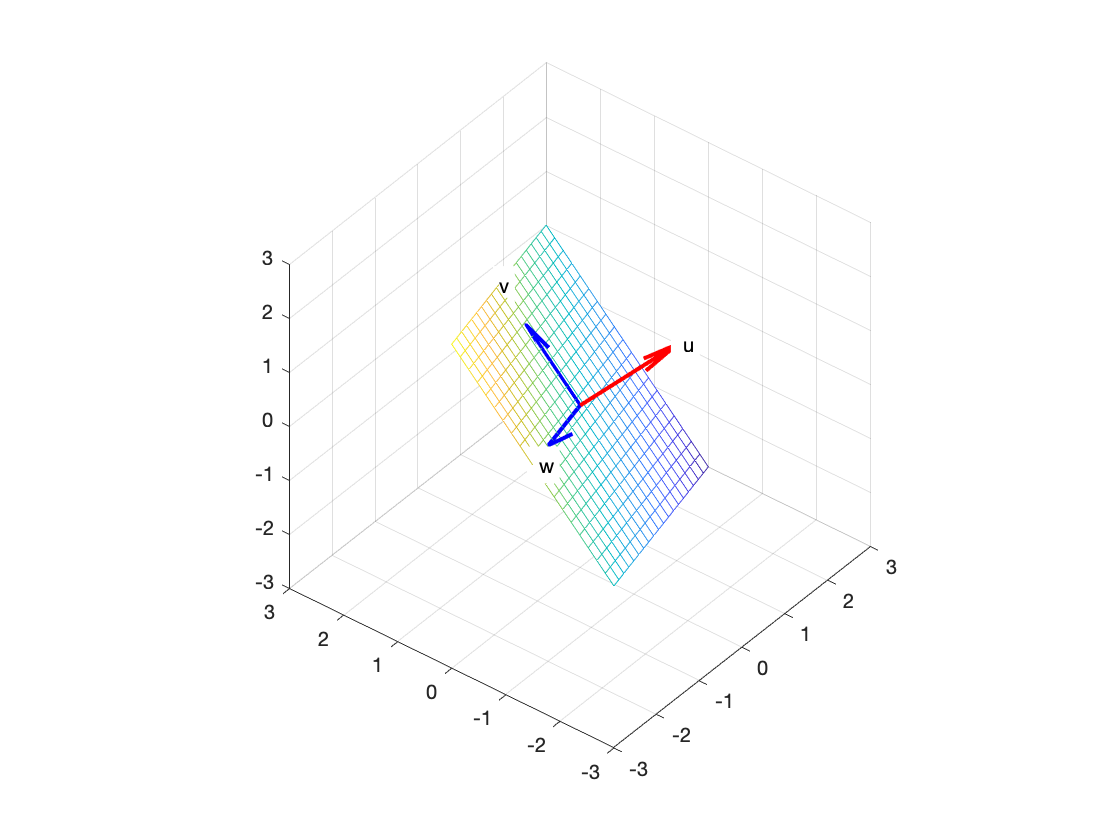

figure
u=[1;-1;1];
v=[0;1;1];
w=[-2;-1;1];
s=linspace(-3/2,3/2,20);
t=linspace(-3/2,3/2,20);
[S,T]=meshgrid(s,t);
X=-2*T;
Y=S-T;
Z=S+T;
mesh(X,Y,Z)
hold on
quiver3(0,0,0,u(1),u(2),u(3),0,'LineWidth',2,'Color','r','MaxHeadSize',2)
quiver3(0,0,0,v(1),v(2),v(3),0,'LineWidth',2,'Color','b','MaxHeadSize',2)
quiver3(0,0,0,w(1),w(2),w(3),0,'LineWidth',2,'Color','b','MaxHeadSize',2)
axis equal
text(1,-1,1,' u','BackgroundColor','w')
text(0,1.5,1.5,'v','BackgroundColor','w')
text(-3,-1.5,1.5,' w','BackgroundColor','w')
hold off
axis equal
view([-51.65 38.40])
hold off

Some might think that these planes are different, but they are not. Let's show some visual evidence of this claim.

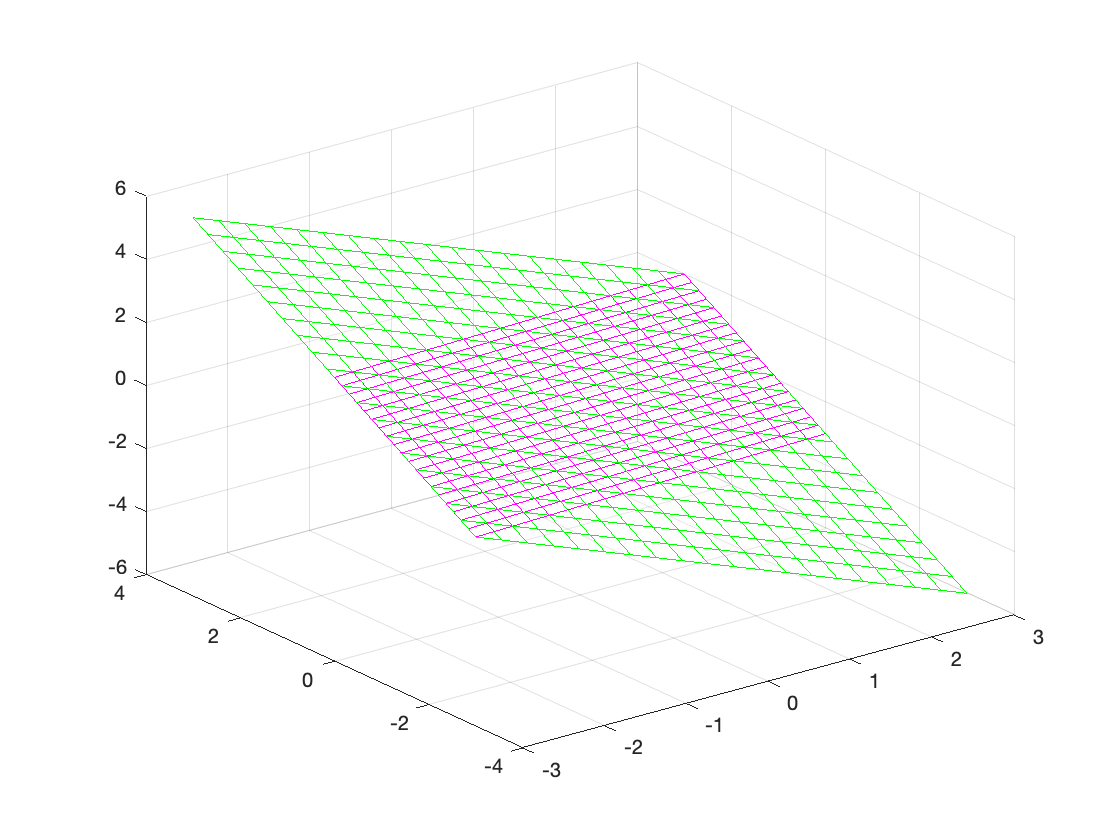

figure
x=linspace(-3,3,20);
y=linspace(-3,3,20);
[X,Y]=meshgrid(x,y);
Z=-X+Y;
mesh(X,Y,Z,'EdgeColor','g','FaceAlpha',0.2)
hold on
s=linspace(-3/2,3/2,20);
t=linspace(-3/2,3/2,20);
[S,T]=meshgrid(s,t);
X=-2*T;
Y=S-T;
Z=S+T;
mesh(X,Y,Z,'EdgeColor','m','FaceAlpha',0.2)

Rotating the image will show that the two planes lie on the same plane. They are just plotted over different $x$ and $y$-values.

# Linear Independence

Here is an important theorem.

# Theorem 1

Suppose that the $S=\left\{\textbf v_1,\ \textbf v_2,\ \ldots,\ \textbf v_n\right\}$ is a collection of nonzero orthogonal vectors. Then, the collection is linear independent.

**Proof: **Suppose that


$$c_1\textbf v_1+c_2\textbf v_2+\cdots c_n \textbf v_n=\textbf 0$$


Now, let's take the dot product of both sides with the vector $\textbf v_1$.


$$\begin{array}{rcl}
\textbf v_1\cdot(c_1\textbf v_1+c_2\textbf v_2+\cdots+c_n\textbf v_n)&=&\textbf v_1\cdot\textbf 0\\
\textbf v_1\cdot(c_1\textbf v_1)+\textbf v_1\cdot(c_2\textbf v_2)+\cdots+\textbf v_1\cdot(c_n\textbf v_n)&=&\textbf 0\\
c_1(\textbf v_1\cdot\textbf v_1)+c_2(\textbf v_1\cdot\textbf v_2)+\cdots+c_n(\textbf v_1\cdot\textbf v_n)&=&\textbf 0
\end{array}$$


Note how we used the distributive property of the dot product and the scalar multipliction property of the dot product in our last two steps. Now, because we have an othogonal set, $\textbf v_1\cdot\textbf v_2=\textbf 0$, ... , $\textbf v_1\cdot\textbf v_n=\textbf 0$. Therefore, all the terms above are $\textbf 0$ except the first term, so our last equation simplifies to:


$$c_1(\textbf v_1\cdot\textbf v_1)=\textbf 0$$


Now, because $\textbf v_1\ne\textbf 0$, that means $\textbf v_1\cdot\textbf v_1\ne 0$. Therefore, $c_1=0$. Now, if we repeat this same process, taking the dot product of both sides of our original equation by $\textbf v_2$, we get:


$$\begin{array}{rcl}
\textbf v_2\cdot(c_1\textbf v_1+c_2\textbf v_2+\cdots+c_n\textbf v_n)&=&\textbf v\cdot\textbf 0\\
\textbf v_2\cdot(c_1\textbf v_1)+\textbf v_2\cdot(c_2\textbf v_2)+\cdots+\textbf v_2\cdot(c_n\textbf v_n)&=&\textbf 0\\
c_1(\textbf v_2\cdot\textbf v_1)+c_2(\textbf v_2\cdot\textbf v_2)+\cdots+c_n(\textbf v_2\cdot\textbf v_n)&=&\textbf 0
\end{array}$$


Now, because we have an othogonal set, all the terms $\textbf v_2\cdot\textbf v_1$, ... , $\textbf v_2\cdot\textbf v_n$ equal zero except the term  $\textbf v_2\cdot\textbf v_2$, so our last equation simplifies to:


$$c_2(\textbf v_2\cdot\textbf v_2)=\textbf 0$$


Now, because $\textbf v_2\ne\textbf 0$, that means $\textbf v_2\cdot\textbf v_2\ne 0$. Therefore, $c_2=0$. 

Hopefully, our readers see a pattern developing. For example, if we take the dot product of both sides of our original equation by $\textbf v_3$, we will show that $c_3=0$. Similarly, we can show that all the $c_i=0$, for $i=1,2,...,n$. Therefore, the only way that 


$$c_1\textbf v_1+c_2\textbf v_2+\cdots c_n \textbf v_n=\textbf 0$$


is if $c_i=0$, for $i=1,2,...,n$. Thus, we've shown that the collection $S=\left\{\textbf v_1,\ \textbf v_2,\ \ldots,\ \textbf v_n\right\}$ of nonzero orthogonal vectors is linearly independent.

# Orthogonal Basis

An **orthogonal basis** for a subspace $W$ of $\mathbb R^n$ is a basis for $W$ that is also an orthogonal set. 

# Theorem 2

Let $\left\{\textbf v_1,\ \textbf v_2,\ \ldots,\ \textbf v_n\right\}$ be an orthogonal basis for a subspace $W$ of $\mathbb R^n$. For each $\textbf x\in \mathbb R^n$, the weights of the linear combination


$$\textbf x=c_1\textbf v_1+c_2\textbf v_2+\cdots+c_n\textbf v_n$$


can be computed by


$$c_k=\frac{\textbf x\cdot\textbf v_k}{\textbf v_k\cdot\textbf v_k}$$


for $k=1,2,\ldots,n$.

**Proof:** The technique for this proof is quite similar to the proof of Theorem 1 above, so we will just show that this is true for $k$. Start with


$$x=c_1\textbf v_1+\cdots+c_k\textbf v_k+\cdots+c_n\textbf v_n$$


and take the dot product of both sides with respect to $\textbf v_k$.


$$\begin{array}{rcl}
\textbf x\cdot\textbf v_k&=&(c_1\textbf v_1+\cdots+c_k\textbf v_k+\cdots+c_n\textbf v_n)\cdot\textbf v_k\\
\textbf x\cdot\textbf v_k&=&(c_1\textbf v_1)\cdot\textbf v_k+\cdots+(c_k\textbf v_k)\cdot\textbf v_k+\cdots+(c_n\textbf v_n)\cdot\textbf v_k\\
\textbf x\cdot\textbf v_k&=&c_1(\textbf v_1\cdot\textbf v_k)+\cdots+c_k(\textbf v_k\cdot\textbf v_k)+\cdots+c_n(\textbf v_n\cdot \textbf v_k)
\end{array}$$


Now, because we have an orthogonal basis, the dot products on the right are all zero except $\textbf v_k\cdot \textbf v_k$. Therefore, we can continue with:


$$\begin{array}{rcl}
\textbf x\cdot\textbf v_k&=&c_k(\textbf v_k\cdot\textbf v_k)\\
c_k&=&\frac{\textbf x\cdot\textbf v_k}{\textbf v_k\cdot\textbf v_k}
\end{array}$$


We're done! 

# Example #4

Express the vector $\textbf x=(4,-3,7)^T$ as a linear combination of the following orthogonal basis vectors


$$\textbf v_1=\pmatrix{2\cr 1\cr 1},\qquad \textbf v_2=\pmatrix{-1\cr 0\cr 2},\qquad\textbf v_3=\pmatrix{2\cr -5\cr 1}$$


for $\mathbb R^3$.

**Solution:** Let's use Matlab to check that we have an orthogonal basis for $\mathbb R^3$.

v1=[2;1;1]; v2=[-1;0;2]; v3=[2;-5;1];
dot(v1,v2)

ans = 0

dot(v1,v3)

ans = 0

dot(v2,v3)

ans = 0

Each dot product is zero so they are mutually orthogonal. Also, notice that we have three vectors in our basis, so this is a basis for $\mathbb R^3$. Now, to use our formula, we need to calculate:


$$\begin{array}{rcl}
\textbf x\cdot \textbf v_1&=&(4)(2)+(-3)(1)+(7)(1)=12\\
\textbf x\cdot \textbf v_2&=&(4)(-1)+(-3)(0)+(7)(2)=10\\
\textbf x\cdot \textbf v_3&=&(4)(2)+(-3)(-5)+(7)(1)=30
\end{array}$$


We can check each of these calculations with Matlab.

x=[4;-3;7];
dot(x,v1)

ans = 12

dot(x,v2)

ans = 10

dot(x,v3)

ans = 30

Same as our hand-calculated answers. Now, we need to calculate:


$$\begin{array}{rcl}
\textbf v_1\cdot\textbf v_1&=&(2)(2)+(1)(1)+(1)(1)=6\\
\textbf v_2\cdot\textbf v_2&=&(-1)(-1)+(0)(0)+(2)(2)=5\\
\textbf v_3\cdot\textbf v_3&=&(2)(2)+(-5)(-5)+(1)(1)=30\\

\end{array}$$


And we can check these with Matlab.

dot(v1,v1)

ans = 6

dot(v2,v2)

ans = 5

dot(v3,v3)

ans = 30

Same as our hand-calculated answers. Now, using the formula


$$c_k=\frac{\textbf x\cdot\textbf v_k}{\textbf v_k\cdot\textbf v_k}$$


from Theorem 2, we can calculate:


$$\begin{array}{rcl}
c_1&=&\frac{\textbf x\cdot\textbf v_1}{\textbf v_1\dot\textbf v_1}=\frac{12}{6}=2\\
c_2&=&\frac{\textbf x\cdot\textbf v_2}{\textbf v_2\dot\textbf v_2}=\frac{10}{5}=2\\
c_3&=&\frac{\textbf x\cdot\textbf v_3}{\textbf v_3\dot\textbf v_3}=\frac{30}{30}=1
\end{array}$$


We can check these calculations with Matlab.

c1=dot(x,v1)/dot(v1,v1)

c1 = 2

c2=dot(x,v2)/dot(v2,v2)

c2 = 2

c3=dot(x,v3)/dot(v3,v3)

c3 = 1

Same as our hand-calculations. Therefore, we've shown that:


$$\begin{array}{rcl}
\textbf x&=&c_1\textbf v_1+c_2\textbf v_2+c_3\textbf v_3\\
\pmatrix{4\cr -3\cr 7}&=&2\pmatrix{2\cr 1\cr 1}+2\pmatrix{-1\cr 0\cr 2}+1\pmatrix{2\cr -5\cr 1}
\end{array}$$


It's pretty easy to see that this is true, but we can also check it with matlab.

x

x =      4
    -3
     7


2*v1+2*v2+1*v3

ans =      4
    -3
     7


Yes, they are the same. 

# Visualizing Example #4

The following image shows the original vectors $\textbf v_1$, $\textbf v_2$, and $\textbf v_3$ from Example #4 in blue. In red, we have the scaled vectors $2\textbf v_1$, $2\textbf v_2$, and $1\textbf v_3$ in red for Example #4. Note that the sum $2\textbf v_1+2\textbf v_2+\textbf v_3$ is the diagonal of the parallelepiped (like the diagonal of the parallelogram in the two dimensional case).

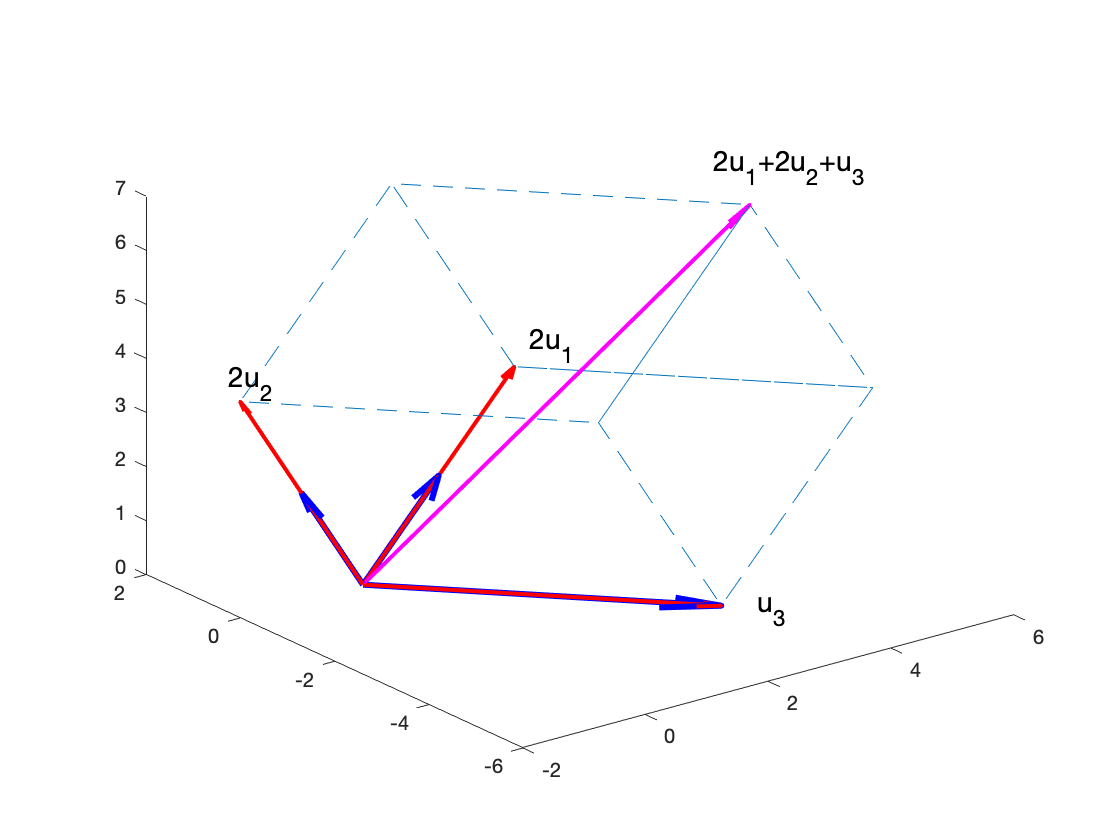

figure
hold on
v1=[2;1;1]; v2=[-1;0;2];v3=[2;-5;1];x=[4;-3;7];
w1=2*v1;w2=2*v2;w3=v3;w=w1+w2+w3;
quiver3(0,0,0,v1(1),v1(2),v1(3),0,'LineWidth',3,'Color','b','MaxHeadsize',0.8)
quiver3(0,0,0,v2(1),v2(2),v2(3),0,'LineWidth',3,'Color','b','MaxHeadsize',0.8)
quiver3(0,0,0,v3(1),v3(2),v3(3),0,'LineWidth',3,'Color','b','MaxHeadsize',0.5)
quiver3(0,0,0,w1(1),w1(2),w1(3),0,'LineWidth',2,'Color','r')
quiver3(0,0,0,w2(1),w2(2),w2(3),0,'LineWidth',2,'Color','r')
quiver3(0,0,0,w3(1),w3(2),w3(3),0,'LineWidth',2,'Color','r')
quiver3(0,0,0,w(1),w(2),w(3),0,'LineWidth',2,'Color','m')
line([4,6,2],[2,-3,-5],[2,3,1],'LineStyle','--')
% line([4,0,-2,2,4],[-3,-5,0,2,-3],[7,5,4,6,7],'LineStyle','--')
line([w2(1),w1(1)+w2(1),w(1),w2(1)+w3(1),w2(1)],...
    [w2(2),w1(2)+w2(2),w(2),w2(2)+w3(2),w2(2)],...
    [w2(3),w1(3)+w2(3),w(3),w2(3)+w3(3),w2(3)],'LineStyle','--')
line([w1(1)+w2(1),w1(1),w1(1)+w3(1)],...
    [w1(2)+w2(2),w1(2),w1(2)+w3(2)],...
    [w1(3)+w2(3),w1(3),w1(3)+w3(3)],'LineStyle','--')
line([w3(1),w1(1)+w3(1),w(1),w2(1)+w3(1),w3(1)],...
    [w3(2),w1(2)+w3(2),w(2),w2(2)+w3(2),w3(2)],...
    [w3(3),w1(3)+w3(3),w(3),w2(3)+w3(3),w3(3)],'Linestyle','--')
text(4.4,2.2,2.2,'2u_1','FontSize',14)
text(-2.2,0,4.4,'2u_2','FontSize',14)
text(2.2,-5.5,1.1,'u_3','FontSize',14)
text(4.4,-3.3,7.7,'2u_1+2u_2+u_3','FontSize',14,'HorizontalAlignment','center')
view(3)
hold off

Note how the blue vectors representing $\textbf v_1$, $\textbf v_2$, and $\textbf v_3$ surely seem orthogonal. 

**Important Note:** We'll soon show more detail to help understand what the geometric meaning of each term of 


$$\textbf x=\frac{\textbf x\cdot\textbf v_1}{\textbf v_1\cdot\textbf v_1}\textbf v_1+\frac{\textbf x\cdot\textbf v_2}{\textbf v_2\cdot\textbf v_2}\textbf v_2+\frac{\textbf x\cdot\textbf v_3}{\textbf v_3\cdot\textbf v_3}\textbf v_3$$


represents. But to take a early peek, examine the image above and note that each term of the final answer


$$\textbf x=2\textbf v_1+2\textbf v_2+\textbf v_3$$


is a projection of the vector $\textbf x$ onto the original vectors $\textbf v_1$, $\textbf v_2$, and $\textbf v_3$. For example, if we project the vector $\textbf x$ onto the vector $\textbf v_1$, we get the vector $2\textbf v_1$. If we project the vector $\textbf x$ onto the vector $\textbf v_2$, we get the vector $2\textbf v_2$. If we project the vector $\textbf x$ onto the vector $\textbf v_3$, we get the vector $\textbf v_3$.

**Gaussian Elimination: ** To find the weights $c_1$, $c_2$, and $c_3$, we can also use a method we've been using since the beginning of class. Take the system


$$\begin{array}{rcl}
\textbf x&=&c_1\textbf v_1+c_2\textbf v_2+c_3\textbf v_3\\
\pmatrix{4\cr -3\cr 7}&=&c_1\pmatrix{2\cr 1\cr 1}+c_2\pmatrix{-1\cr 0\cr 2}+c_3\pmatrix{2\cr -5\cr 1}
\end{array}$$


and create the augmented matrix.


$$\pmatrix{2 & -1 & 2 & 4\cr 1 & 0 & -5 & -3\cr 1 & 2 & 1 & 7}$$


Since we have each of these columns already stored in the vectos v1, v2, v3, and x, we can create our augmented matrix as follows.

A=[v1,v2,v3,x]

A =      2    -1     2     4
     1     0    -5    -3
     1     2     1     7


Now we can row reduce.

rref(A)

ans =      1     0     0     2
     0     1     0     2
     0     0     1     1


Note that this also gives us $c_1=2$, $c_2=2$, and $c_3=1$.